First Lets Define the Input Parameters

clear();

carrier_freq = 10

carrier_freq = 10

pulse_freq = 1

pulse_freq = 1

sampling_rate = 10e3

sampling_rate = 10000

duty_cycle = 0.2

duty_cycle = 0.2000

ramp_time = (1 / pulse_freq) * duty_cycle * 0.05

ramp_time = 0.0100

total_time = 10

total_time = 10

Now Lets Determine The Desired Frequency and Delta Phases

cycle_period = (1 / pulse_freq)

cycle_period = 1

max_num_cycles = ceil(total_time / cycle_period)

max_num_cycles = 10

pulse_time = cycle_period * duty_cycle

pulse_time = 0.2000

break_time = cycle_period - pulse_time

break_time = 0.8000

freq_keysteps_single = [carrier_freq, (carrier_freq + 1 / pulse_time)]

freq_keysteps_single =     10    15


dphase_keysteps_single = [pi, 0]

dphase_keysteps_single =     3.1416         0


keytime_deltas_single = [break_time, pulse_time]

keytime_deltas_single =     0.8000    0.2000



freq_keysteps = repmat(freq_keysteps_single, [1, max_num_cycles])

freq_keysteps =     10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15


keytime_deltas = repmat(keytime_deltas_single, [1, max_num_cycles])

keytime_deltas =     0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000    0.8000    0.2000


dphase_keysteps = repmat(dphase_keysteps_single, [1, max_num_cycles])

dphase_keysteps =     3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0


keytimes = cumsum(keytime_deltas)

keytimes =     0.8000    1.0000    1.8000    2.0000    2.8000    3.0000    3.8000    4.0000    4.8000    5.0000    5.8000    6.0000    6.8000    7.0000    7.8000    8.0000    8.8000    9.0000    9.8000   10.0000


Let's Generate the Default Phase Ramp For each Unique Frequency Jumps - Phase Jump Pair

freq_jumps = [freq_keysteps(1:(end - 1))', freq_keysteps(2:end)']

freq_jumps =     10    15
    15    10
    10    15
    15    10
    10    15
    15    10
    10    15
    15    10
    10    15
    15    10


num_jumps = size(freq_jumps, 1)

num_jumps = 19

unique_freq_jumps = unique(freq_jumps, "rows")

unique_freq_jumps =     10    15
    15    10


num_unique_freq_jumps = size(unique_freq_jumps, 1)

num_unique_freq_jumps = 2

freq_jump_id = zeros(1, num_jumps);

dphase_jumps = [dphase_keysteps(1:(end - 1))', dphase_keysteps(2:end)']

dphase_jumps =     3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416


unique_dphase_jumps = unique(dphase_jumps, 'rows')

unique_dphase_jumps =          0    3.1416
    3.1416         0


num_unique_dphase_jumps = size(unique_dphase_jumps, 1)

num_unique_dphase_jumps = 2

dphase_jump_id = zeros(1, num_jumps);

jump_id_pairs = zeros([num_jumps, 2]);
unique_jump_pairs = zeros([0, 2]);
pair_jump_id = zeros(1, num_jumps);

for iJump = 1:num_jumps
    fj = freq_jumps(iJump, :);
    freq_jump_id(iJump) = find(all(fj == unique_freq_jumps, 2));

    dpj = dphase_jumps(iJump, :);
    dphase_jump_id(iJump) = find(all(dpj == unique_dphase_jumps, 2));

    jump_pair = [freq_jump_id(iJump), dphase_jump_id(iJump)];
    jump_id_pairs(iJump, :) = jump_pair;
    this_jump_id = find(all(jump_pair == unique_jump_pairs, 2));
    if isempty(this_jump_id)
        this_jump_id = size(unique_jump_pairs, 1) + 1
        unique_jump_pairs = [unique_jump_pairs; jump_pair];
    end
    pair_jump_id(iJump) = this_jump_id;
end

this_jump_id = 1

this_jump_id = 2


freq_jump_id

freq_jump_id =      1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1


dphase_jump_id

dphase_jump_id =      2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2


jump_id_pairs

jump_id_pairs =      1     2
     2     1
     1     2
     2     1
     1     2
     2     1
     1     2
     2     1
     1     2
     2     1


unique_jump_pairs

unique_jump_pairs =      1     2
     2     1


pair_jump_id

pair_jump_id =      1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1


syms x c_f1 c_f2 c_t1 c_t2
freqramp_inst_freq_sfx = c_f1 + (c_f2 - c_f1) / (c_t2 - c_t1) * (x - c_t1)

$$freqramp\_inst\_freq\_sfx = c_{\mathrm{f1}}-\frac{\left(c_{\mathrm{f1}}-c_{\mathrm{f2}}\right)\,\left(c_{\mathrm{t1}}-x\right)}{c_{\mathrm{t1}}-c_{\mathrm{t2}}}$$

freqramp_phase_template_sfx = 2 * pi * int(freqramp_inst_freq_sfx, x)

$$freqramp\_phase\_template\_sfx = 2\,\pi \,\left(c_{\mathrm{f1}}\,x+\frac{\left(c_{\mathrm{f1}}-c_{\mathrm{f2}}\right)\,{\left(c_{\mathrm{t1}}-x\right)}^{2}}{2\,\left(c_{\mathrm{t1}}-c_{\mathrm{t2}}\right)}\right)$$

phase_ramps_fxs = cell(1, num_unique_jumps);

Unrecognized function or variable 'num_unique_jumps'.

for iJump = 1:num_unique_freq_jumps
    freq_jump = unique_freq_jumps(iJump, :);
    f1 = freq_jump(1);
    f2 = freq_jump(2);
    t1 = -(ramp_time / 2);
    t2 = -t1;
    delta_f = f2 - f1;
    delta_t = t2 - t1;
    
    freqramp_phase_sfx = subs(freqramp_phase_template_sfx, ...
        [c_f1, c_f2, c_t1, c_t2], ...
        [f1, f2, t1, t2]);
    freqramp_phase_fx = @(x) subs(freqramp_phase_sfx);
    phase_ramps_fxs{iJump} = freqramp_phase_fx;
end
phase_ramps_fxs


t_test = -ramp_time:(1/sampling_rate):ramp_time

t_test =    -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0094   -0.0093   -0.0092   -0.0091   -0.0090   -0.0089   -0.0088   -0.0087   -0.0086   -0.0085   -0.0084   -0.0083   -0.0082   -0.0081   -0.0080   -0.0079   -0.0078   -0.0077   -0.0076   -0.0075   -0.0074   -0.0073   -0.0072   -0.0071   -0.0070   -0.0069   -0.0068   -0.0067   -0.0066   -0.0065   -0.0064   -0.0063   -0.0062   -0.0061   -0.0060   -0.0059   -0.0058   -0.0057   -0.0056   -0.0055   -0.0054   -0.0053   -0.0052   -0.0051


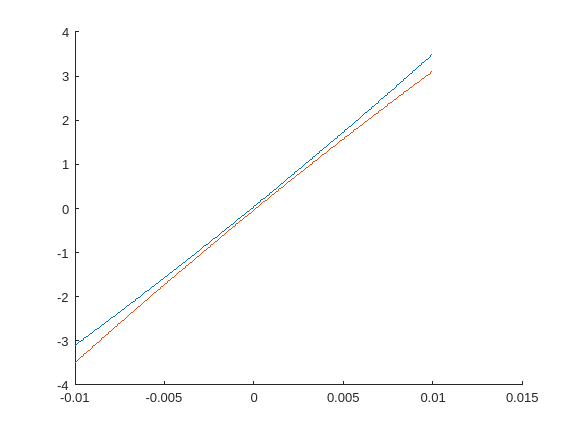


figure();
hold on
plot(t_test, phase_ramps_fxs{1}(t_test))
plot(t_test, phase_ramps_fxs{2}(t_test))

Misc Tests

syms x_sym x1_sym x2_sym real
teepee_sfx = 1 ...
    * (-1 * abs((4 * 1 / (x2_sym - x1_sym) ^ 2) ...
                        * (x_sym - ((x1_sym + x2_sym) / 2))) ...
              + (2 * 1 / (x2_sym - x1_sym)))

$$teepee\_sfx = -\frac{2}{x_{1,\mathrm{sym}}-x_{2,\mathrm{sym}}}-\frac{4\,\left|\frac{x_{1,\mathrm{sym}}}{2}+\frac{x_{2,\mathrm{sym}}}{2}-x_{\mathrm{sym}}\right|}{{\left(x_{1,\mathrm{sym}}-x_{2,\mathrm{sym}}\right)}^{2}}$$

xx =    -2.0000   -1.9960   -1.9920   -1.9880   -1.9840   -1.9800   -1.9760   -1.9720   -1.9680   -1.9640   -1.9600   -1.9560   -1.9520   -1.9479   -1.9439   -1.9399   -1.9359   -1.9319   -1.9279   -1.9239   -1.9199   -1.9159   -1.9119   -1.9079   -1.9039   -1.8999   -1.8959   -1.8919   -1.8879   -1.8839   -1.8799   -1.8759   -1.8719   -1.8679   -1.8639   -1.8599   -1.8559   -1.8519   -1.8478   -1.8438   -1.8398   -1.8358   -1.8318   -1.8278   -1.8238   -1.8198   -1.8158   -1.8118   -1.8078   -1.8038



teepee_fx = matlabFunction(subs(teepee_sfx, [x1_sym, x2_sym], [-1, 1]))

teepee_fx = function_handle with value:
    @(x_sym)-abs(x_sym)+1.0


teepee_fx = @(x) subplus(teepee_fx(x))

teepee_fx = function_handle with value:
    @(x)subplus(teepee_fx(x))


int_teepee_fx = @(x) double(subs(int_teepee_sub_sfx, x_sym, xx))

int_teepee_fx = function_handle with value:
    @(x)double(subs(int_teepee_sub_sfx,x_sym,xx))



teepee_y = teepee_fx(xx);

teepee_y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



figure();
plot(xx, teepee_y, LineWidth=3)

xx = linspace(-2, 2, 1000)

xx =    -2.0000   -1.9960   -1.9920   -1.9880   -1.9840   -1.9800   -1.9760   -1.9720   -1.9680   -1.9640   -1.9600   -1.9560   -1.9520   -1.9479   -1.9439   -1.9399   -1.9359   -1.9319   -1.9279   -1.9239   -1.9199   -1.9159   -1.9119   -1.9079   -1.9039   -1.8999   -1.8959   -1.8919   -1.8879   -1.8839   -1.8799   -1.8759   -1.8719   -1.8679   -1.8639   -1.8599   -1.8559   -1.8519   -1.8478   -1.8438   -1.8398   -1.8358   -1.8318   -1.8278   -1.8238   -1.8198   -1.8158   -1.8118   -1.8078   -1.8038


x1 = -1

x1 = -1

x2 = 1

x2 = 1

y1 = 0

y1 = 0

y2 = 1

y2 = 1

int_teepee_y = integrated_teepee(xx, x1, x2, y1, y2);

num_sigma = 4

num_sigma = 4

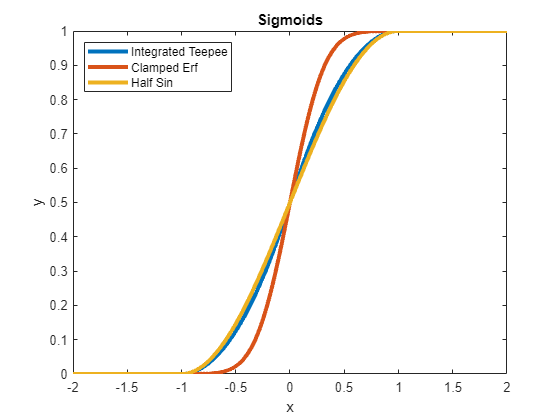

clamped_erf_y = clamped_erf(xx, x1, x2, y1, y2, num_sigma);
half_sin_y = half_sin(xx, x1, x2, y1, y2);

figure();

plot(xx, int_teepee_y, LineWidth=3)
hold on
plot(xx, clamped_erf_y, LineWidth=3)
plot(xx, half_sin_y, LineWidth=3)
title('Sigmoids');
ylabel('y')
xlabel('x')
legend({'Integrated Teepee', 'Clamped Erf', 'Half Sin'}, Location="northwest")


figure();
dx = xx(2) - xx(1)

dx = 0.0040

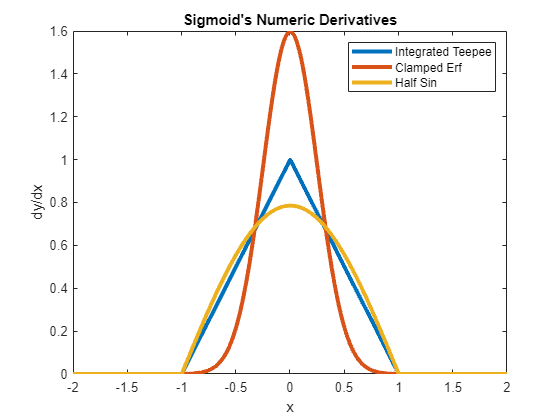

d_int_teepee_y = [0, diff(int_teepee_y)] / dx;
d_clamped_erf_y = [0, diff(clamped_erf_y)] / dx;
d_half_sin_y = [0, diff(half_sin_y)] / dx;
plot(xx, d_int_teepee_y, LineWidth=3)
hold on
plot(xx, d_clamped_erf_y, LineWidth=3)
plot(xx, d_half_sin_y, LineWidth=3)
title('Sigmoid''s Numeric Derivatives');
ylabel('dy/dx');
xlabel('x')
legend({'Integrated Teepee', 'Clamped Erf', 'Half Sin'})

Functions

function output = clamped_erf(x, x1, x2, y1, y2, num_sigma)
    output = zeros(size(x), 'like', x);
    is_clip_1 = x <= x1;
    is_clip_2 = x >= x2;
    output(is_clip_1) = y1;
    output(is_clip_2) = y2;
    
    is_fx_defined = ~is_clip_1 & ~is_clip_2;
    if ~any(is_fx_defined)
        return
    end
    
    dt = x2 - x1;
    sigma = dt / (num_sigma * 2);
    mu = (x1 + x2) / 2;
    
    cdf_fx = @(x, mu) 1 / 2 * (1 + erf((x - mu) / (sigma * sqrt(2))));
    
    err_val = [0-cdf_fx(-sigma*num_sigma, 0), 1-cdf_fx(sigma*num_sigma, 0)];
    correction_fx = @(x) err_val(1) + diff(err_val) / dt * (x - x1);
    
    sigmoid_fx = @(x) y1 + (y2 - y1) * (cdf_fx(x, mu) + correction_fx(x));
    output(is_fx_defined) = sigmoid_fx(x(is_fx_defined));
end

function output = integrated_teepee(x, x1, x2, y1, y2)
    output = zeros(size(x), 'like', x);
    
    isPreTeepee = x <= x1;
    output(isPreTeepee) = 0;
    isPostTeepee = x >= x2;
    output(isPostTeepee) = 1;
    isConstRegion = isPreTeepee | isPostTeepee;
    
    if ~all(isConstRegion)
        tMidpoint = (x1 + x2) / 2;
        dx = -x2 + x1;
        
        isXPrePeak = (x < tMidpoint) & ~isConstRegion;
        isXPostPeak = ~isXPrePeak & ~isConstRegion;
        
        output(isXPrePeak) = ...
            1.0 ./ dx .^ 2 .* (-x(isXPrePeak) + x1) .^ 2 .* 2.0;
        output(isXPostPeak) = ...
            (1.0 ./ dx .^ 2 .* (-x(isXPostPeak) + x2) .^ 2 .* -2.0) + 1;
    end
    
    output = y1 + (output * (y2 - y1));
end

function output = half_sin(x, x1, x2, y1, y2)
    output = zeros(size(x), 'like', x);
    is_clip_1 = x <= x1;
    is_clip_2 = x >= x2;
    output(is_clip_1) = 0;
    output(is_clip_2) = 1;

     is_fx_defined = ~is_clip_1 & ~is_clip_2;
    if any(is_fx_defined)
        delta_x = x2 - x1;
        half_sin_fx = @(x) (sin((2 * pi * (x - x1) / 2 / delta_x) - (pi / 2)) / 2) + (1 / 2);
        output(is_fx_defined) = half_sin_fx(x(is_fx_defined));
    end

    output = y1 + (output * (y2 - y1));
end

function y = wrapTo2PiStable(x, tol)
    y = wrapTo2Pi(x);
    y(y > ((2 * pi) - tol)) = 0;
end

function y = wrapToPiStable(x, tol)
    y = wrapToPi(x);
    y(y < (-pi + tol)) = pi;
end